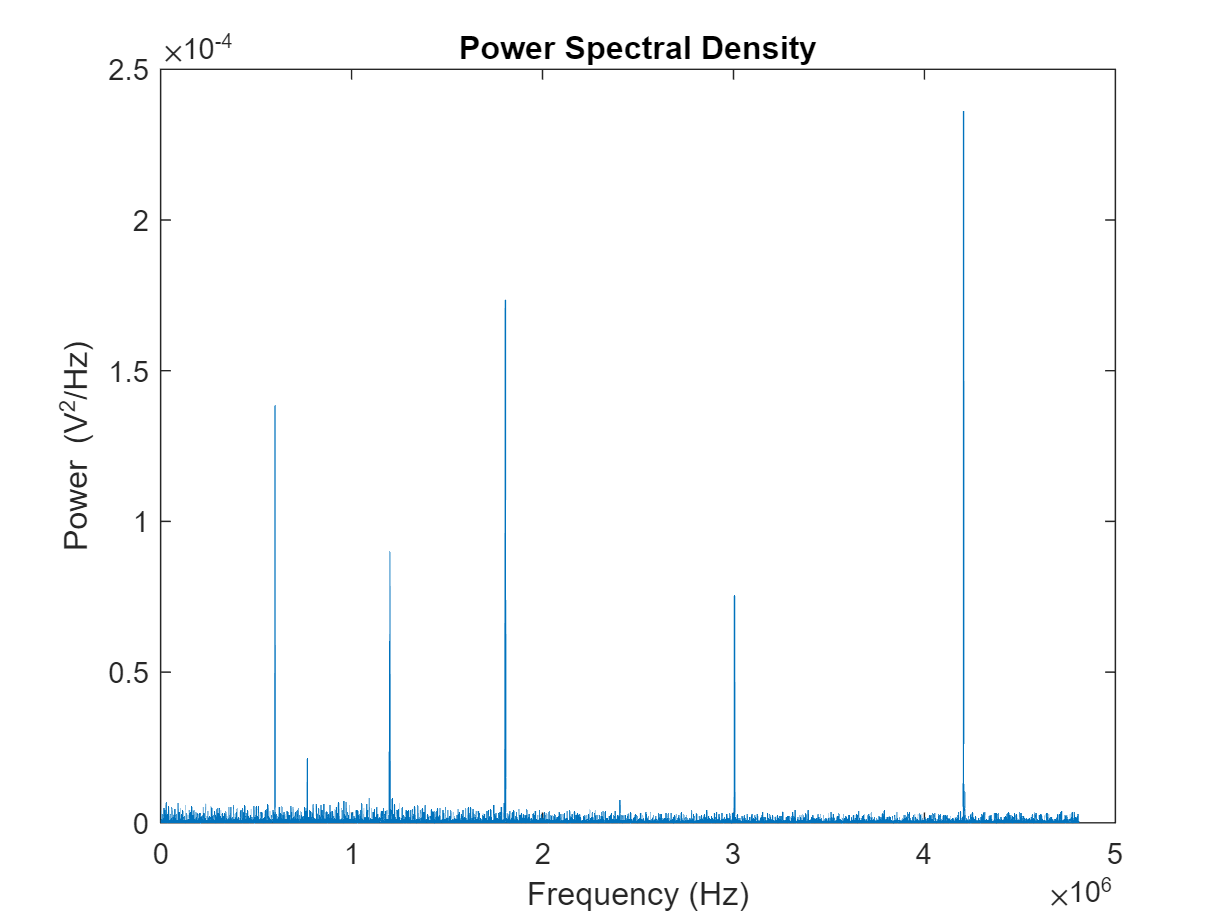

clear;
data = [];
num_files = 2;
for i = 1:num_files
    file_name = sprintf('C:\\Users\\phmm\\Documents\\SquareWave\\Week4SquareWaveProbe2_%d.mat', i);
    loaded_data = load(file_name);
    A = loaded_data.A;
    
    data = [data; A];
end
load("C:\\Users\\phmm\\Documents\\SquareWave\\Week4SquareWaveProbe2_1.mat");
data(isinf(A)|isnan(A)) = 0; % Replace Infinite and Nan values from data with 0

N = Length*num_files;
Fs = 1/Tinterval; % Sampling frequency
threshold = 0.1e-4;
delta_f = Fs/N; % Frequency bin width

% Convert from dBu to V^2/Hz
V_squared = (10.^((data/20) - log10(0.775))).^2; 
PSD = V_squared/(delta_f); 


% Compute the one-sided power spectral density
Y = fft(PSD);

P2 = abs(Y/N);
P1 = P2(1:(N/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*((0:(N/2))/N);

% Plot the power spectral density
plot(f(2:end),P1(2:end))
title('Power Spectral Density')
xlabel('Frequency (Hz)')
ylabel('Power (V^2/Hz)')

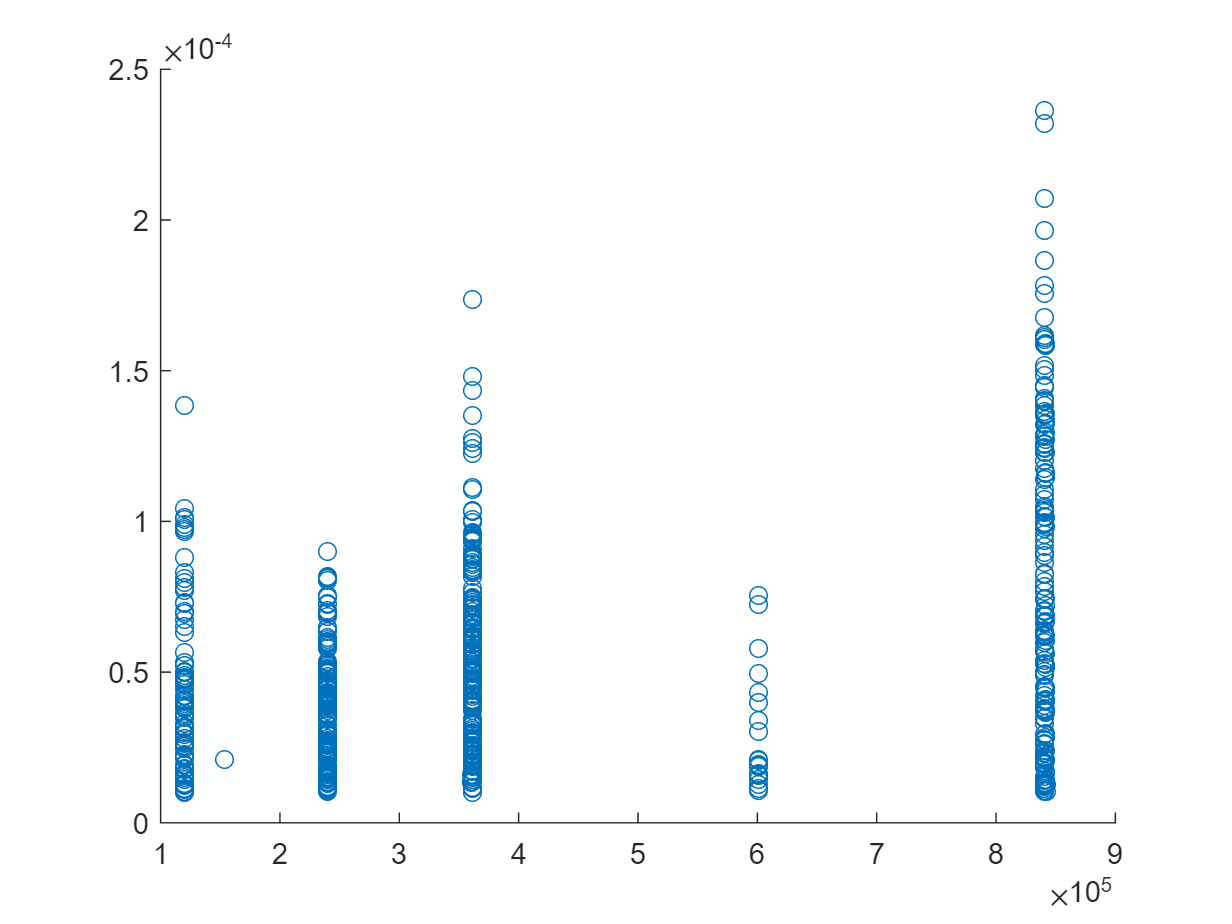


[peaks, indexes] = findpeaks(P1);
NotablePeaks = peaks(peaks > threshold);
PeakIndexes = indexes(peaks > threshold);
PeakFrequencies = f(PeakIndexes);
PeakFrequencies = PeakFrequencies';
NotablePeaks;
scatter(PeakIndexes, NotablePeaks);


%save(" INSERT FILE LOCATION ","PeakFrequencies", "NotablePeaks", "f","P1")
